## Simple circuit analysis

This example goes through creating a **circuit** object from a **netlist**, which is contained in a text file. We start by calling the Circuit class and giving it the path to the netlist. The netlist automatically gets stored as a property called '**list**' on the circuit object.

circuit = Circuit('circuits/passive/RLC.txt');
circuit.list

ans =     'Vcc 3 0 DC Vcc
     Vs 4 1 AC 0
     R2 3 2 1000
     R1 1 0 1000
     C1 4 0 0.000001
     C2 2 4 0.00001
     '


To symbolically **analyze** the circuit object, we give it to the **ELAB** class. This performs **MNV** to define the equations, which describe the circuit.

ELAB.analyze(circuit)

Symbolic analysis successful (1.30184 sec).


An **e**lectrical **c**ircuit is just subclass of a system, which can we represented in any number of ways. For example as a transfer function in the **s**ymbolic **d**omain. This can be done using the '**ec2sd**'-function.

sym_TF = ELAB.ec2sd(circuit, 3, 2)

Symbolic transfer function calculated successfully (9.945300e-03 sec).


$$sym\_TF = \frac{v_{2}}{v_{3}}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\mathrm{Vcc}\,\left(C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1\right)}$$

Say the netlist contained numerical values for some, or all of its components. The evaluate function will use whatever equations were found by ELAB.analyze() to numerically evaluate the circuit. This numerical evaluation can now be used to create a Matlab-transfer-function object.

ELAB.evaluate(circuit)


Numerical evaluation successful (0.381248 sec).


num_TF = ELAB.ec2tf(circuit, 3, 2)

Transfer function object created successfully (5.122530e-02 sec).

num_TF =
 
     1100 s + 100000
  ---------------------
  s^2 + 2100 s + 100000
 
Continuous-time transfer function.



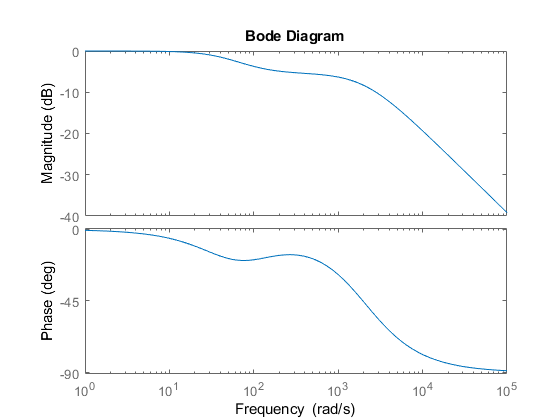

bode(num_TF);

During analysis, all node voltages and element currents were symbolically defined.

circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=-\frac{R_{1}\,s\,\left(C_{1}\,\mathrm{Vs}-C_{2}\,\mathrm{Vcc}+C_{2}\,\mathrm{Vs}+C_{1}\,C_{2}\,R_{2}\,\mathrm{Vs}\,s\right)}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1}\\ v_{2}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1}\\ v_{3}=\mathrm{Vcc}\\ v_{4}=\frac{\mathrm{Vs}+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1} \end{array}\right)$$

And during evaluation, they were all numerically evaluated.